Problem 2

R_Mars = 3397;
r_p = 1.5*R_Mars;
r_a = 6.5*R_Mars;
M = -90;
mu_Mars = 42828.314258067;
mu = mu_Mars;

e = 5/8;
a = r_p/(1-e)

a = 13588

p = r_p*(1+e)

p = 8.2802e+03

h = sqrt(p*mu)

h = 1.8832e+04

period = 2*pi*sqrt(a^3/mu)

period = 4.8089e+04

epsilon = -mu/(2*a)

epsilon = -1.5760

E = -120.7691;
theta = 2*atand(sqrt((1+e)/(1-e))*tand(E/2))

theta = -149.4535

r = a*(1-e*cosd(E))

r = 1.7933e+04

v = sqrt(2*mu/r-mu/a)

v = 1.2746

gamma = acosd(sqrt(mu*p)/(r*v))

gamma = 34.5256

acosd((1+e*cosd(theta))/sqrt(1+e^2+2*e*cosd(theta)))

ans = 34.5256

t_tp = deg2rad(M)/sqrt(mu/a^3)

t_tp = -1.2022e+04

r0 = [1.7932*10^4, 0, 0]' % r theta h

r0 =        17932
           0
           0


v0 = 1.2746*[-sind(gamma) cosd(gamma) 0]' % r theta h

v0 =    -0.7224
    1.0501
         0


R = [cosd(theta) sind(theta) 0;-sind(theta) cosd(theta) 0;0 0 1]

R =    -0.8612   -0.5082         0
    0.5082   -0.8612         0
         0         0    1.0000


r0_ep = R'*r0

r0_ep = 	1.0e+04 *

   -1.5443
   -0.9114
         0


v0_ep = R'*v0

v0_ep =     1.1559
   -0.5372
         0


tf_tp = t_tp+1/2*period;
M_f = sqrt(mu/a^3)*(tf_tp)

M_f = 1.5708

rad2deg(M_f)

ans = 90

E_f = kepler_eqn(M_f, e)

E_f = 2.1078

rad2deg(E_f)

ans = 120.7691

theta_f = 2*atan(sqrt((1+e)/(1-e))*tan(E_f/2))

theta_f = 2.6085

rad2deg(theta_f)

ans = 149.4535

n = sqrt(mu/a^3);
dE = E_f - deg2rad(E)

dE = 4.2156

f = 1 - a/r*(1-cos(dE))

f = -0.1188

g = (tf_tp-t_tp) + (sin(dE) - dE)/n

g = -1.4949e+04


rf = p/(1+e*cos(theta_f));
fd = n*a^2/(r*rf)*sin(dE)

fd = -6.5950e-05

gd = 1 - a/rf*(1-cos(dE))

gd = -0.1188


dtheta = theta_f-deg2rad(theta)

dtheta = 5.2169


f1 = 1 - rf/p*(1-cos(dtheta))

f1 = -0.1188

g1 = (r*rf)/sqrt(mu*p)*sin(dtheta)

g1 = -1.4949e+04

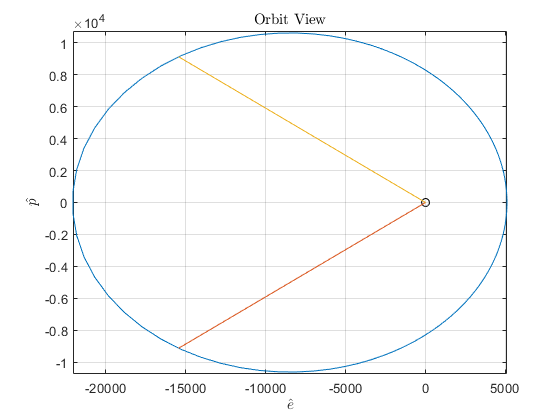

plot_orbit(e, p)
plot([0, r*cosd(theta)],[0, r*sind(theta)])
plot([0, rf*cos(theta_f)], [0, rf*sin(theta_f)])

## Problem 3

mu_Earth = 398600.4415;
mu = mu_Earth;
R_Earth = 6378.1363;
a = 20*R_Earth;
e = 0.6;
i = 34;
OMEGA = 45;
omega = 30;
theta = 235;

theta_a0 = theta-omega

theta_a0 = 205

p = a*(1-e^2)

p = 8.1640e+04

E = 2*atand(tand(theta_a0/2)*sqrt((1-e)/(1+e)))

E = -132.1760

r = p/(1+e*cosd(theta_a0))

r = 1.7895e+05

a*(1-e*cosd(E))

ans = 1.7895e+05

v = sqrt(2*mu/r - mu/a)

v = 1.1533

period = 2*pi*sqrt(a^3/mu)

period = 4.5342e+05

M = deg2rad(E) - e*sind(E)

M = -1.8623

rad2deg(M)

ans = -106.6994

t_tp = M/sqrt(mu/a^3)

t_tp = -1.3439e+05

period - (2*pi+M)/sqrt(mu/a^3)

ans = 1.3439e+05

gamma = -acosd(sqrt(mu*p)/(r*v))

gamma = -29.0659

r_rth = [r 0 0]';
v_rth = v*[sind(gamma) cosd(gamma) 0]'

v_rth =    -0.5603
    1.0081
         0


C_313 = [cosd(OMEGA)*cosd(theta)-sind(OMEGA)*cosd(i)*sind(theta), -cosd(OMEGA)*sind(theta)-sind(OMEGA)*cosd(i)*cosd(theta), sind(OMEGA)*sind(i);
    sind(OMEGA)*cosd(theta)+cosd(OMEGA)*cosd(i)*sind(theta), -sind(OMEGA)*sind(theta)+cosd(OMEGA)*cosd(i)*cosd(theta) -cosd(OMEGA)*sind(i);
    sind(i)*sind(theta), sind(i)*cosd(theta), cosd(i)]

C_313 =     0.0746    0.9155    0.3954
   -0.8858    0.2430   -0.3954
   -0.4581   -0.3207    0.8290


r_xyz = C_313*r_rth

r_xyz = 	1.0e+05 *

    0.1335
   -1.5851
   -0.8197


v_xyz = C_313*v_rth

v_xyz =     0.8810
    0.7412
   -0.0667


C_3 = [cosd(OMEGA) sind(OMEGA) 0;-sind(OMEGA) cosd(OMEGA) 0;0 0 1]

C_3 =     0.7071    0.7071         0
   -0.7071    0.7071         0
         0         0    1.0000


r_n = C_3*r_xyz

r_n = 	1.0e+05 *

   -1.0264
   -1.2153
   -0.8197


v_n = C_3*v_xyz

v_n =     1.1471
   -0.0988
   -0.0667


t2_tp = t_tp+3*24*3600;
M2 = sqrt(mu/a^3)*t2_tp

M2 = 1.7296

rad2deg(M2)

ans = 99.0985

E2 = kepler_eqn(M2, e)

E2 = 2.2108

rad2deg(E2)

ans = 126.6716

theta_a2 = 2*atan(tan(E2/2)*sqrt((1+e)/(1-e)))

theta_a2 = 2.6496

rad2deg(theta_a2)

ans = 151.8108

r2 = a*(1-e*cos(E2))

r2 = 1.7327e+05

v2 = sqrt(2*mu/r2 - mu/a)

v2 = 1.2149

gamma2 = acos(sqrt(mu*p)/(r2*v2))

gamma2 = 0.5416

rad2deg(gamma2)

ans = 31.0292

r2_rth = [r2 0 0]';
v2_rth = v2*[sin(gamma2) cos(gamma2) 0]'

v2_rth =     0.6263
    1.0411
         0


rad2deg(theta_a2)-theta_a0

ans = -53.1892

rad2deg(E2) - E

ans = 258.8477

theta2 = rad2deg(theta_a2) + omega

theta2 = 181.8108

C_313 = [cosd(OMEGA)*cosd(theta2)-sind(OMEGA)*cosd(i)*sind(theta2), -cosd(OMEGA)*sind(theta2)-sind(OMEGA)*cosd(i)*cosd(theta2), sind(OMEGA)*sind(i);
    sind(OMEGA)*cosd(theta2)+cosd(OMEGA)*cosd(i)*sind(theta2), -sind(OMEGA)*sind(theta2)+cosd(OMEGA)*cosd(i)*cosd(theta2) -cosd(OMEGA)*sind(i);
    sind(i)*sind(theta2), sind(i)*cosd(theta2), cosd(i)]

C_313 =    -0.6882    0.6083    0.3954
   -0.7253   -0.5636   -0.3954
   -0.0177   -0.5589    0.8290


r2_xyz = C_313 * r2_rth

r2_xyz = 	1.0e+05 *

   -1.1925
   -1.2567
   -0.0306


v2_xyz = C_313 * v2_rth

v2_xyz =     0.2022
   -1.0410
   -0.5929


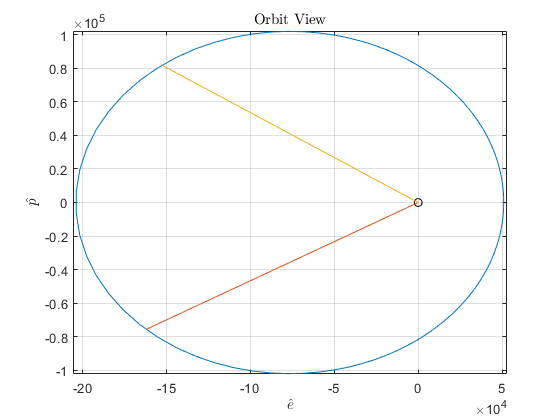

plot_orbit(e, p)
plot([0, r*cosd(theta_a0)],[0, r*sind(theta_a0)])
plot([0, r2*cos(theta_a2)], [0, r2*sin(theta_a2)])

## Problem 4

mu = mu_Earth;
r1_xyz = [0.15 -1.44 -0.65]'*R_Earth

r1_xyz = 	1.0e+03 *

    0.9567
   -9.1845
   -4.1458


v1_xyz = [6.62 2.7 -1.56]'

v1_xyz =     6.6200
    2.7000
   -1.5600



r1 = norm(r1_xyz)

r1 = 1.0122e+04

v1 = norm(v1_xyz)

v1 = 7.3176

a = -mu/2/(v1^2/2-mu/r1)

a = 1.5811e+04

h = norm(cross(r1_xyz, v1_xyz))

h = 7.3092e+04

p = h^2/mu

p = 1.3403e+04

e = sqrt(1-p/a)

e = 0.3903

h_hat = cross(r1_xyz, v1_xyz)/h

h_hat =     0.3492
   -0.3551
    0.8672


i = acos(h_hat(3))

i = 0.5213

rad2deg(i)

ans = 29.8668

RAAN = -atan(h_hat(1)/h_hat(2))

RAAN = 0.7770

rad2deg(RAAN)

ans = 44.5201

r1_hat = r1_xyz/r1

r1_hat =     0.0945
   -0.9074
   -0.4096


theta1_hat = cross(h_hat, r1_hat)

theta1_hat =     0.9323
    0.2250
   -0.2833


theta1 = atan2(r1_hat(3),theta1_hat(3))

theta1 = -2.1759

rad2deg(theta1)

ans = -124.6678

r1_d = dot(v1_xyz,r1_hat)

r1_d = -1.1852

theta_a1 = -acos((p/r1-1)/e)

theta_a1 = -0.5907

rad2deg(theta_a1)

ans = -33.8428


omega = theta1-theta_a1

omega = -1.5852

rad2deg(omega)

ans = -90.8250


gamma1 = acos(sqrt(mu*p)/(r1*v1))

gamma1 = 0.1627

rad2deg(gamma1)

ans = 9.3213


E1 = 2*atan(tan(theta_a1/2)*sqrt((1-e)/(1+e)))

E1 = -0.3976

rad2deg(E1)

ans = -22.7827


M1 = E1-e*sin(E1)

M1 = -0.2465

rad2deg(M1)

ans = -14.1240

t1_tp = M1/sqrt(mu/a^3)

t1_tp = -776.2720

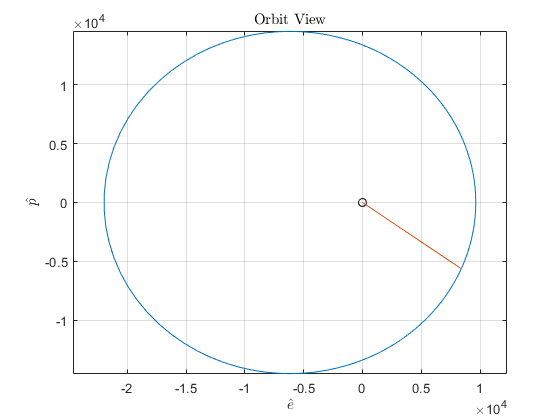

plot_orbit(e, p)
plot([0, r1*cos(theta_a1)],[0, r1*sin(theta_a1)])